# Systems Decomposition 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Imagine trying to assemble a puzzle without first sorting the pieces—it would be difficult to know where to begin. Similarly, in engineering, tackling a complex system at once can be daunting and inefficient. System decomposition is a methodical way for engineers to manage complexity. By breaking down a large system into smaller, more manageable subsystems and components, engineers can focus on solving specific parts of the problem without losing sight of the overall goals. This approach not only clarifies the relationships and interactions among different parts but also enables parallel development and testing. In this script, we will examine how system decomposition helps make large engineering challenges more approachable.

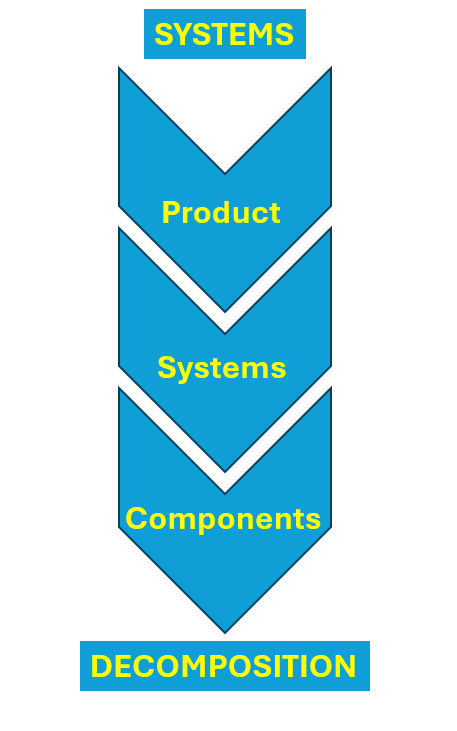

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Decomposing a problem

Imagine being tasked with building a car from the ground up. It's far more complex than just buying parts and snapping them together. What if, instead of building the entire car from the start, we begin by designing individual components like the battery or shock absorber and gradually assemble the full vehicle, system by system? Complex systems or problems can be solved in stages by decomposition. Decomposition divides a problem into smaller, more manageable parts, making it easier to verify that each part meets its requirements. The left side of the V-model demonstrates the process in which decomposition takes place. At the highest level of the decomposition process is the product or overall system; which is associated with a problem statement and high level requirements for the system. A product consists of multiple interconnected systems (or subsystems), each containing components that enable the overall system to function effectively. Both systems and components have associated requirements, all of which are traceable along the left side of the V-model. After defining system-level requirements, a Preliminary Design Review (PDR) is conducted. Once component-level requirements are established, a Critical Design Review (CDR) follows. The diagram below illustrates the V-model decomposition path:

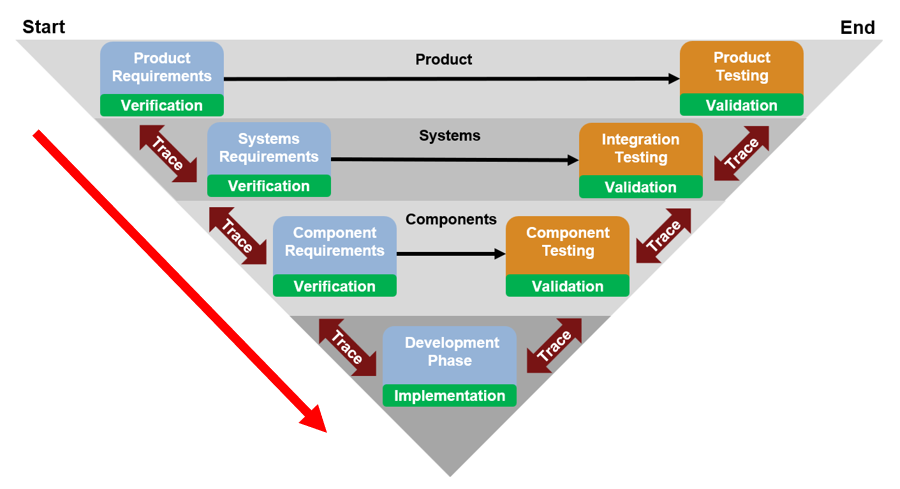

Let's [revisit the bungee jumping example](matlab:open('./IntroToProblemSolving.mlx')) to identify how this problem can be decomposed in reference to the V-model:

- Product Level - **Bungee Jumping Product**

- Systems Level - **Bungee Cord, Bungee Jumper, Environment (Air) **

- Components Level - **Spring Constant, Jumper Mass, Air Density**

  **Try**. Now, review the bungee jumping mathematical model and examine the different block names using the following button: 

 

% Check if project is open and add path
if isempty(matlab.project.rootProject)
    addpath(genpath(pwd));
end

% Open Simulink model for bungee jumping with drag 
open_system("Models/BungeeJumpingDrag.slx")

 **Exercise 1. **One of the systems in the Bungee Jumping Product is the Bungee Cord. Which of the following blocks in the model would be a **component** of the Bungee Cord System? Please select all that apply and click the **Submit Answer** button below. 

exerciseSol1(...
    A = false, ...
    B = true, ...
    C = true, ...
    D = true);

Correct! These are all examples of components that make up the Bungee Cord system.


## System Decomposition: Delivery Drone

We will explore the problem-solving techniques we have learned up to this point and apply them to package delivery using a quadcopter. Those techniques include problem statements, requirements, and tests for this product. Since we are decomposing the problem of a delivery drone, these techniques will be applied in layers as described in the V-model. Let's review the product level of the quadcopter system:

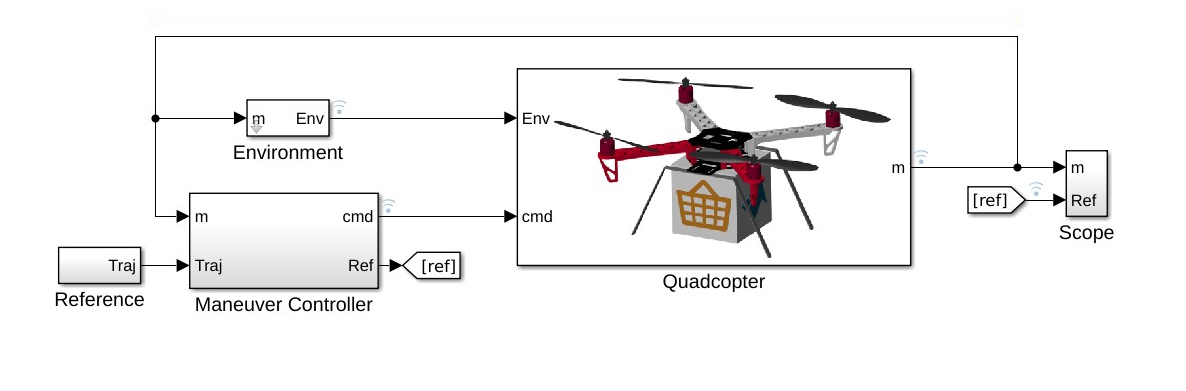

  **Try**. Feel free to explore the systems of the quadcopter model for the drone delivery product using the following button. **This is optional.**

 **Note**. This button will also close the previous model (bungee jumping). Future buttons in this script will also close previous models before opening new models.

 **Warning**. If you are using MATLAB Online right now, the following button will open a **new instance** of MATLAB Online for the delivery drone model, and therefore exit out of this script. To return to this script, use/copy/save this link: [**Systems Decomposition**](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Engineering-Problem-Solving&project=EngineeringProblemSolving.prj&file=Scripts/SystemsDecomposition.mlx). 

 

% Close previous model
close_system("Models/BungeeJumpingDrag.slx",0);

% Open drone project in MATLAB Online
web('https://matlab.mathworks.com/open/github/v1?repo=mathworks/Quadcopter-Drone-Model-Simscape&project=Quadcopter_Drone.prj');

 **Pro-tip. **Once the quadcopter model window is open, click on the maximize button in the top right corner to expand the model window full screen. Then, click on the canvas area and press the space button. This will resize the model for easier viewing.

The following problem statement describes our objective for this quadcopter:

When thinking about the types of requirements we will have for this product, recall some of the potential questions that may arise:

- How much weight can the drone carry?

- How far can the drone fly?

- What kind of environment will the drone operate in?

- What is the allowable size(s) for a drone to perform this kind of task?

- What does the drone have to interact with? (People, Buildings, Communication towers, Other aircraft, etc.)

### Product Level

The following table describes the high-level requirements of the delivery drone:

The following diagram shows the various systems involved with the development of a delivery drone. This diagram is known as a system architecture, and was created using [System Composer](https://www.mathworks.com/products/system-composer.html). System architectures are useful for planning and understanding the interfaces of a system before it is constructed. Referring back to the introduction, this diagram would be consistent with sorting your puzzle pieces before assembling your puzzle. Each of the systems in the diagram are connected by ports for the purpose of allowing the flow of information between the systems:

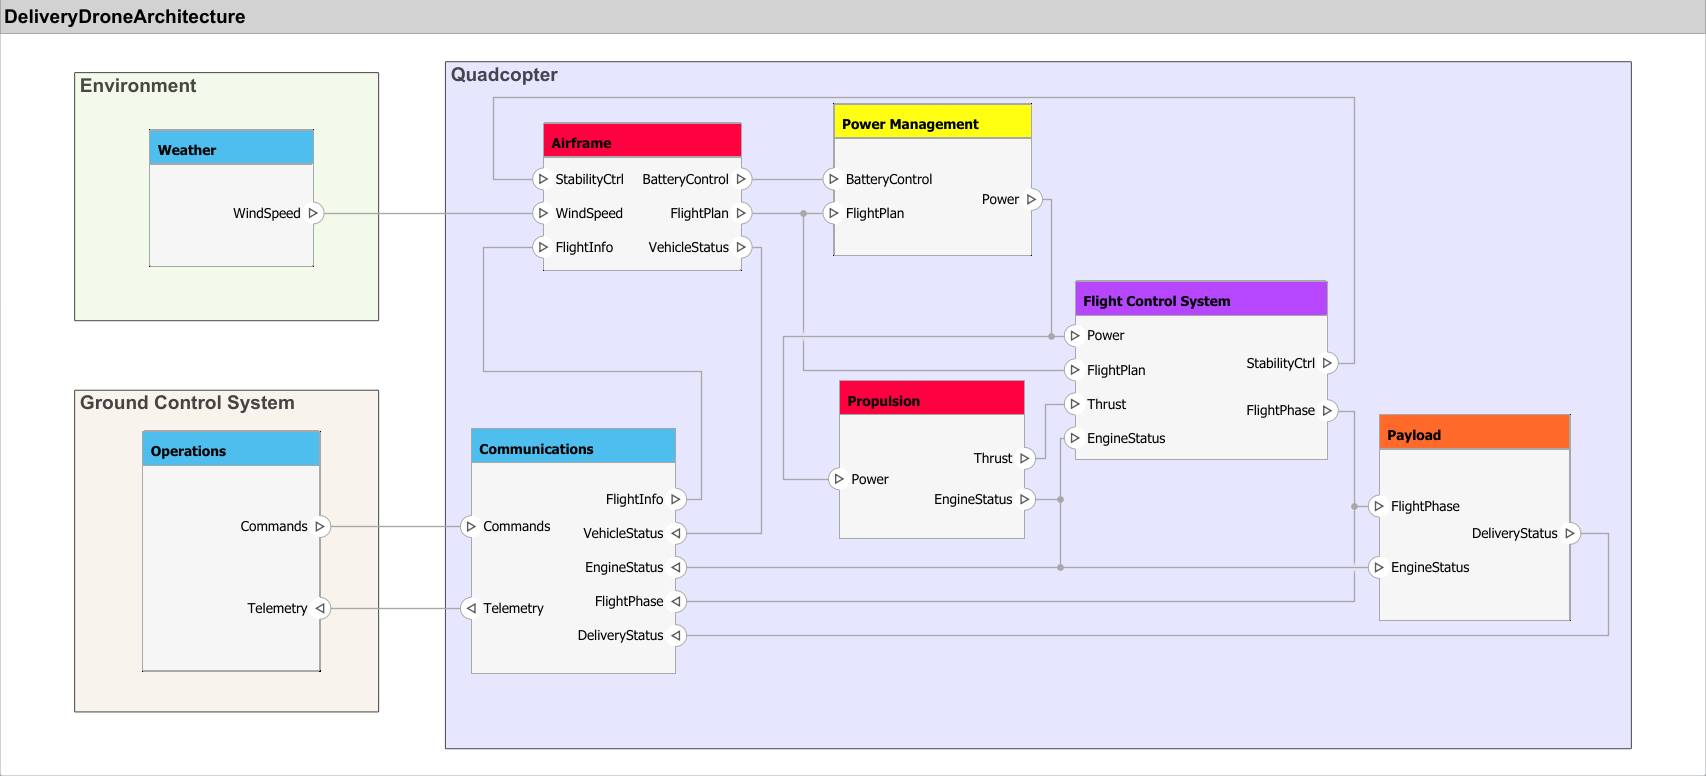

**This diagram is a simplified representation of a general quadcopter's interconnected systems. It does not depict the exact model shown ****above****, nor does it include all possible connections. Instead, it serves as a conceptual guide to illustrate how various systems can influence one another. **This diagram was created with a general color-coding scheme in System Composer. In this example, specific colors have been assigned to represent certain systems as follows:

  **Try**. Feel free to explore the system architecture model for the drone delivery product. Clicking on the interconnection lines will show how the data flows between systems. **This is optional.**

 

% Open Simulink model for delivery drone architecture
open_system("Models/DeliveryDroneArchitecture.slx");

 **Exercise 2. **Using the system architecture diagram or model, what systems interface with **outputs** from the **Propulsion system**?

exerciseSol2("Flight Control System, Payload, Communications"); 

Correct!


Now that we have an idea of the architecture for the overall product, we can observe that it would be difficult to figure out how to solve the customer's problem at this level. Therefore, we will look at decomposing the problem further to the system level. *For simplicity, we will be developing only one system and one component of this delivery drone product. The same decomposition process would be followed in developing the other systems and components.*

### Systems Level

Let's focus on the **flight control system (FCS) **part of the product architecture above. An FCS is one of the most critical systems in any flying vehicle. It consists of sensors, computers, mechanisms, and software that work together to manage the aircraft’s maneuvering and stability. The FCS receives and interprets pilot commands, adjusts control surfaces accordingly, and helps the aircraft navigate safely through various weather conditions. Let's review the FCS requirements in relation to the product requirements:

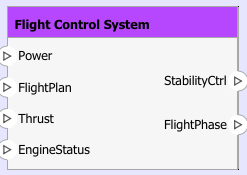

System architectures are also useful for understanding interfaces—specifically, how information or [data types](https://www.mathworks.com/help/matlab/numeric-types.html) are defined and exchanged between systems through their ports. As an engineer, working with different teams and disciplines is common. Each team has their own defined interfaces for their system. Learning how one team's interfaces connect with another is a major part of defining the right system. It is crucial to understand interfaces to make better design choices as a solution becomes clearer for the problem being solved. Even at the system level, we can see that it's still difficult to begin building an FCS given the requirements. Let's try decomposing once more—to the component level.

### Components Level

Components, unlike products and systems, are actionable tasks that can be worked on. One component of an FCS is its software, which can be developed using various programming languages. *One of the capabilities of this software is enabling the quadcopter to hover in place. *Let's review the hover-related requirements for the FCS software:

Now that we have an idea of a specific component that impacts the flight control system, let's take a look at how this *hover capability *might be implemented through software via a Simulink model. In this test scenario, the quadcopter will begin at a height of 15 m above the ground before it reaches the hover flight phase. A set of equations defines the motion of the quadcopter and is represented as a block diagram:

Open and run   the following model for the flight control software. Then, open the scope block labeled "Results" to observe the modeled quadcopter hover. The hover condition is met when the position is constant and its velocity is ~0. 

 

% Close previous model
close_system("Models/DeliveryDroneArchitecture.slx",0);

% Open Simulink model for Flight Control Software
open_system("Models/FlightControlSoftware.slx");

## Detailed Design

This phase of decomposition fully specifies the system’s components—including software, hardware, and communications—for implementation, focusing on their development to meet system requirements. Key aspects include verification through detailed specifications, well-defined data exchange interfaces, and architectural alignment, as well as evaluating component alternatives through trade studies.

Throughout this process, model fidelity can change significantly as the design becomes more defined and complete, increasing complexity with refinement. For example, an early flight control software model may use a lookup table to define quadcopter lift, whereas more advanced models may incorporate an electric motor driving the propellers with associated performance data sheets for a more realistic representation.

### Design Verification

On the left side of the V-model, the focus is on verification. The most effective way to describe verification activities is by answering a key question: Did we satisfy the intended design requirements? Or, more simply, did we define the right quadcopter?

Satisfying the design requirements can be straightforward—provided the system's requirements have been properly defined and evaluated. Let's examine the requirements and verification tests for the flight control software and how it connects to the quadcopter product:

 

% Close previous model 
close_system("Models/FlightControlSoftware.slx",0);

% Open Simulink model for FCS requirements and tests
open_system("Models/FlightControlSoftwareReqx.slx");
slreq.open("Data/FCSHoverRequirements.slreqx");
slreq.app.CallbackHandler.onRefreshAllHyperlink('standalone');
sltest.testmanager.view;
sltest.testmanager.load("Data/FCSHoverTests.mldatx");

Observe that not all requirements are filled out for the flight control system. Since our focus is the hover control component, only the requirements for that part of the software have been defined. Taking a step back, the takeaway is to build each component piece by piece. Once that is achieved, they can be tested individually for accuracy and then brought together to attain a fully-defined flight control system. Let's verify the design of the hover control component by running tests tied to requirements:

 

% Run FCS software model
outHover = sim("Models/FlightControlSoftwareReqx.slx","StopTime","50");

% Run Tests 
sltest.testmanager.run;

This is the value of decomposition—taking something as amorphous as a quadcopter for delivery to having a actionable task such as creating software for a flight control system. Now that the hover module is complete and verified with passing tests, think about how to expand on this system and others that are part of the greater quadcopter architecture. The problem statement requires a lot of effort and churn, and now we've seen the tools that are available to turn the original problem statement into a viable engineering solution.

### Trade Studies

Let's examine another system of the quadcopter—the **power management system**, which consists of components such as a battery. What if we have specific requirements about weight limitations, power output, and cost? We must manage and balance all of these needs to support the original problem statement. This means that our solution for a battery can take many forms. How can we find the right battery that meets the weight, power needed, and budget of our system? Which requirements are we able to compromise on? 

Trade studies provide a means to test a variety of permutations in a system to see which is the best fit in meeting your requirements. During the process of decomposition, it is very likely trade studies will occur at the component level for the purpose of optimizing your design. Let's perform our own trade study on potential battery options to power the quadcopter. The following is the trade criteria for a successful battery selection:

[In the previous script](matlab:open('./DefiningRequirements.mlx')), we explored regulatory requirements and their impact on delivery drone design. In the United States, the certification process is governed by 14 CFR 119 [1]. Under these guidelines, the Federal Aviation Administration (FAA) determines what the total weight restrictions will be for a delivery drone on a case-by-case basis. This could mean a loss in revenue for not being able to deliver certain size packages. To mitigate these risks for Sundaland, Inc., performing trades with respect to total weight may provide some margin to carry larger packages while keeping the drone weight lower.

  **Try**. Open the Battery Trade Study model with the button below. Adjust the "Trade Selection" rotary dial to the trade you want to observe, and then simulate the model using the run icon  .

 **Pro-tip. **The name of the active trade will be displayed at the top of the block titled "Battery Options" in the model.

 

% Close previous model and current session of requirements and test files
close_system("Models/FlightControlSoftwareReqx.slx",0);

% Clear requirements and tests
slreq.clear(); 
sltest.testmanager.clear;
sltest.testmanager.clearResults;
sltest.testmanager.close;

% Open Simulink model for battery trade study 
open_system("Models/TradeStudyBattery.slx");

 **Exercise 3. **Based on the trade study model, you may observe that none of the trades are ideal or satisfy all the criteria, but they are still the best options on the market. With that in mind, which trade seems to be the best value for this scenario?

exerciseSol3("Trade 2"); 

Yes, mostly! Cost and weight are well within bounds and power density
is right on the cusp of acceptable. Power requirements in the design may
be a bit easier to adjust compared to staying within tight weight targets,
which gives this option the edge.


Let's clean up our working environment using the button below:

 

% Close all model windows and clear workspace
close_system("Models/TradeStudyBattery.slx",0);

% Check if project is open and remove path
if isempty(matlab.project.rootProject)
    warning('off','MATLAB:rmpath:DirNotFound');
    rmpath(genpath(pwd));
end

## Development

At last, the meticulous planning and organization have paid off! Every piece of the puzzle has been identified and described, and the design has reached a mature stage after successfully passing both the PDR and CDR. The next stage, development, typically follows one of two paths: in-house manufacturing or supplier acquisition—essentially, build or buy. Manufacturing in-house streamlines integration and ensures performance expectations are met but can be costly without the right processes, tools, and expertise. Acquiring components from a supplier reduces organizational workload and may be more cost-effective, though it introduces risks such as potential delays that could slow time to market for the product. As an example of in-house development, we can take the **flight control software model **and generate executable C from it using [Simulink Coder](https://www.mathworks.com/products/simulink-coder.html) with the intent of deploying it on hardware. The goal is to validate whether the algorithm developed in the model produces the expected real-world behavior when implemented in hardware. Use the checkbox below to view the code generation process for the flight control software model:

devFlag = true;

if devFlag
    % Display video of code generation process
    web('https://github.com/MathWorks-Teaching-Resources/Engineering-Problem-Solving/wiki/Flight-Control-Simulink-Code-Generation'); %#ok<UNRCH>
end

When code is generated through Simulink Coder, it will create a folder of compiled code on your local file path that has the model name appended with **"_grt_rtw"**. Once there is confidence in the code generated, it can be deployed to the hardware target of choice for component/system/product testing. For more information about code generation and hardware deployment with Simulink, please refer to the Further Exploration section.

## Next Steps

This script utilized problem statements and requirements in the problem solving process to break down a problem into actionable parts. In the next section, we will conclude the problem solving process by integrating and testing the various parts of our system to finalize our solution.

## Glossary

**V-model** - A graphical representation of the systems development life cycle. (↑ Return to Text)

**Problem Statement **- A statement that concisely describes a problem and the needs that must be addressed, showing the gap between current and desired state. (↑ Return to Text)

**Requirement** - A documented need or condition that a particular product, service, or system must satisfy. (↑ Return to Text)

**PDR **- Ensures the design meets requirements and objectives. (↑ Return to Text)

**CDR - **Confirms the design is complete and production-ready. (↑ Return to Text)

**Trade Study **-  A process where different options or solutions to a problem are compared against a set of criteria to identify the most balanced and optimal choice. (↑ Return to Text)

**Verification** - The process of establishing truth, accuracy, or validity that the problem being solved is the correct one. (↑ Return to Text)

**Certification** - In the context of aviation, this means the FAA has confirmed that a product or operation meets FAA safety requirements and standards, ensuring safe operation for the public. (↑ Return to Text)

## Further Exploration

- [Requirements Toolbox](https://www.mathworks.com/products/requirements-toolbox.html)

- [System Composer Onramp](https://matlabacademy.mathworks.com/details/system-composer-onramp/orsc)

- [Simulink Code Generation ](https://www.mathworks.com/help/rtw/gs/generate-code-by-using-simulink-coder-quick-start.html)

- [Embedded Code Generation](http://www.mathworks.com/help/ecoder/gs/generate-code-by-using-embedded-coder-quick-start.html)

- [Connection to Hardware/Hardware Support](https://www.mathworks.com/hardware-support.html?q=&page=1)

- [Real-Time Simulation and Testing](https://www.mathworks.com/help/slrealtime/gs/real-time-simulation-and-testing.html)

## References

[1] National Archives (n.d.). *Delivery Drone Regulations*. Code of Federal Regulations. Retrieved March 12, 2025, from [https://www.ecfr.gov/current/title-14/chapter-I/subchapter-G/part-119?toc=1](https://www.ecfr.gov/current/title-14/chapter-I/subchapter-G/part-119?toc=1) (↑ Return to Text)

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function exerciseSol1(opts)
    % Provides solution for Exercise 1
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ~any([opts.A opts.B opts.C opts.D])
        disp("Please select all that apply!")
    elseif [opts.B opts.C opts.D] %#ok<BDSCA>
        disp("Correct! These are all examples of components that make up the Bungee Cord system.")
    elseif opts.A && ~any([opts.B opts.C opts.D])
        warning("Incorrect. The First Integration block represents velocity and is not part of the bungee cord system.")
    elseif opts.B && ~any([opts.A opts.C opts.D])
        warning("Incorrect. The Cord Stretch Point block is a part of the Bungee Cord system. However, there is more than one answer.")
    elseif opts.C && ~any([opts.A opts.B opts.D])
        warning("Incorrect. Bungee Cord Position block is a measurement of the system's position. However, there is more than one answer.")
    elseif opts.D && ~any([opts.A opts.B opts.C])
        warning("Incorrect. The Spring Constant block is a part of the Bungee Cord system. However, there is more than one answer.")
    else % Any other combination
        warning("Almost! You have not selected all the components that make up the Bungee Cord system.")
    end
end

function exerciseSol2(choices)
    % Provides solution for Exercise 2
    arguments
        choices (1,1) string {mustBeMember(choices,["Select an answer" "Flight Control System, Payload, Communications" "Weather, Operations, Airframe" "Communications, Power Management, Payload" "Flight Control System, Airframe, Weather"])}
    end

    if choices == "Select an answer"
    else
        if choices == "Flight Control System, Payload, Communications"
            disp("Correct!");
        elseif choices == "Weather, Operations, Airframe"
            warning("Incorrect. Pay close attention to the arrow connections leaving the propulsion system.");
        elseif choices == "Communications, Power Management, Payload"
            warning("Incorrect. Pay close attention to the arrow connections leaving the propulsion system.");
        elseif choices == "Flight Control System, Airframe, Weather"
            warning("Incorrect. Pay close attention to the arrow connections leaving the propulsion system.");
        end
    end
end

function exerciseSol3(choices)
    % Provides solution for Exercise 3
    arguments
        choices (1,1) string {mustBeMember(choices,["Select an answer" "Trade 1" "Trade 2" "Trade 3"])}
    end

    if choices == "Select an answer"
    else
        if choices == "Trade 1"
            warning("Incorrect. While cost and weight are low, the power density is not close enough to the range needed.");
        elseif choices == "Trade 2"
            disp("Yes, mostly! Cost and weight are well within bounds and power density" + newline + "is right on the cusp of acceptable. Power requirements in the design may" + newline + "be a bit easier to adjust compared to staying within tight weight targets," + newline + "which gives this option the edge.");
        elseif choices == "Trade 3"
            warning("Perhaps? While it meets the power density and cost criteria, it fails in the weight category, which is crucial for design and meeting regulations.");
        end
    end
end